# L10 examples

NOTES:

zblk, ublk = 1 -> blocking factor -> we don't use them

W,V = 0 -> we don't use them

h = Ts

cmode = 0 always (because we do state measurements)

solver = 'qp_as'

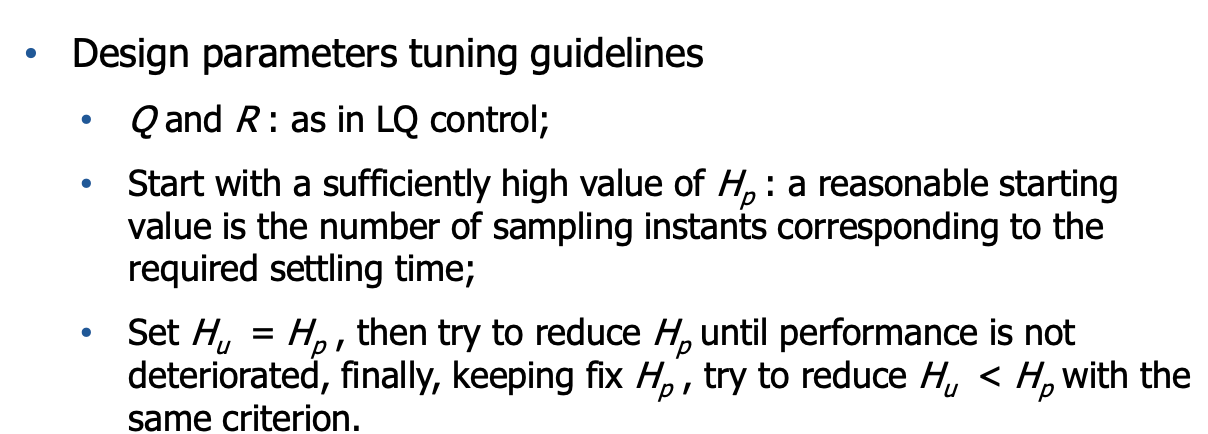

## Exercise 1

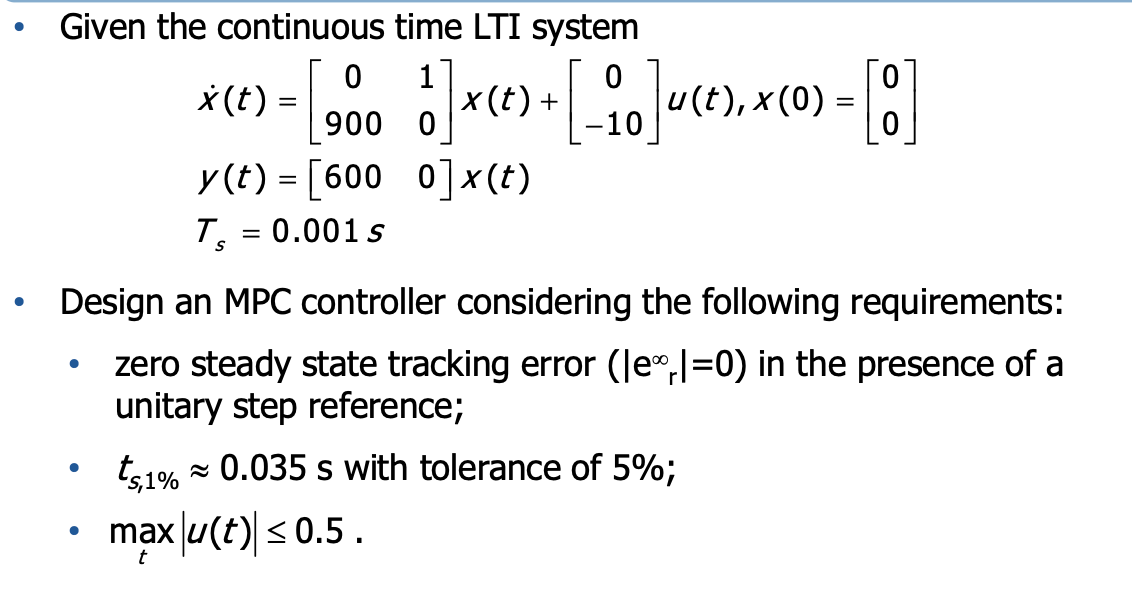

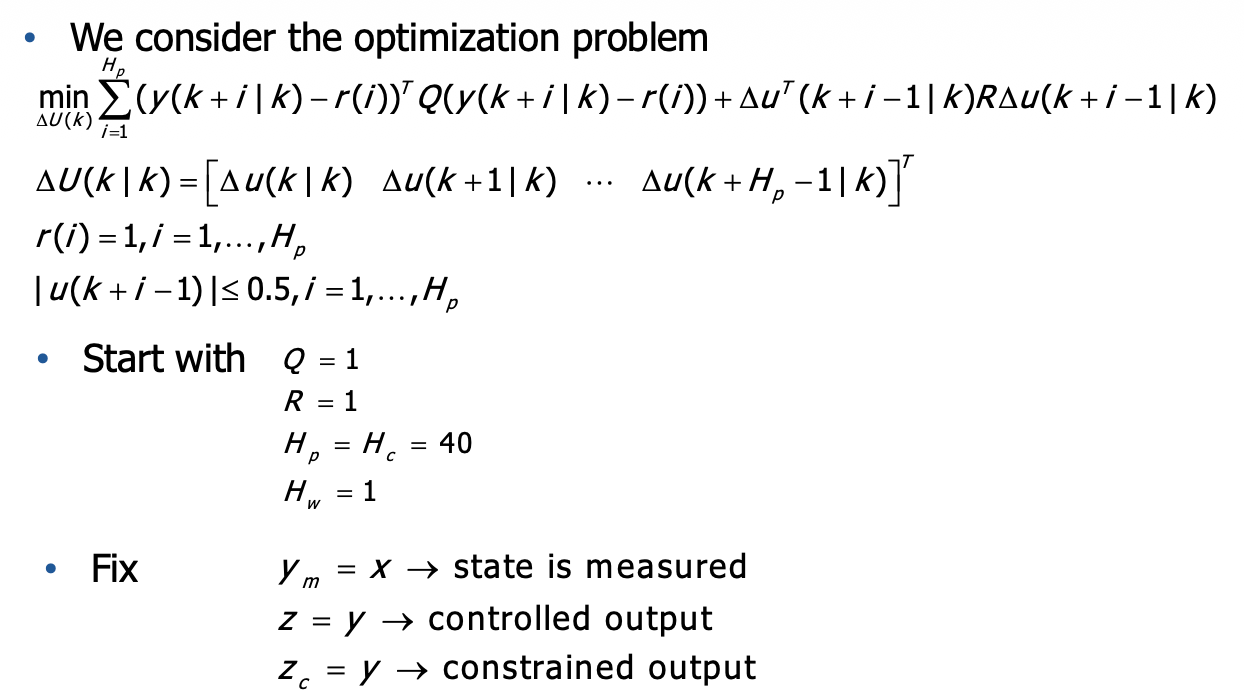

close all
clear
clc

% define the ct state matrices & initial condition
A = [0 1; 900 0];
B = [0;-10];
C = [600 0];
D = 0;
sys = ss(A,B,C,D);
sys_x = ss(A,B,eye(2),0); % system with output = state -> it is needed for simulation
x0 = [0;0];

% discretize the model
Ts = 0.001;
sys_dt = c2d(sys,Ts,'zoh');
Ad = sys_dt.a;
Bd = sys_dt.b;
Cd = sys_dt.c;
Dd = sys_dt.d;

#### Set design parameters for MPCtools

Cy = eye(2); % measured output -> all states measured -> we assume that the output measured is the state => C must be eye
Cz = Cd; Dz = 0; % controlled output
Cc = Cd; Dc = 0; % constrained output = controlled output
Q = 1;
R = 1;
cmode = 0; % state feedback mode
h = Ts;
z_max = [inf]; % output constraints (no constraints but we need to define these limitations)
z_min = [-inf]; 
u_max = [0.5]; % input constraints
u_min = [-0.5]; 
du_max = [inf]; % rate constraints
du_min = [-inf]; 
Hp = 40; % prediction horizon
% why 40? We want to "see" at least for the settling time interval 
% in order to optimize. Ts = 1 ms and settling time = 35 ms, so Hp > 35
Hu = 40; % control horizon
Hw = 1; % first penalty sample 
z_blk = 1; % no blocking
u_blk = 1; % no blocking

#### Compute MPC controller

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...


#### Simulation

t_sim = 0.2;
rho = 1;
out = sim('sim_pendolum.slx');

Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.05
Update start,

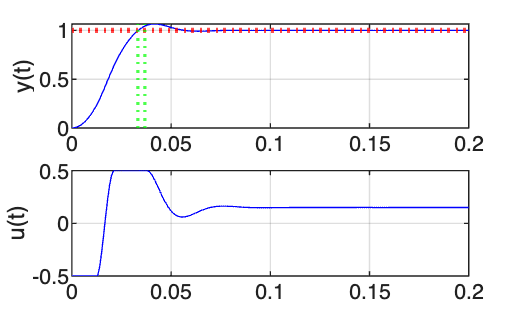

figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(1.01, ':r', 'LineWidth',1.2)
yline(0.99, ':r', 'LineWidth',1.2)
xline(0.035*1.05, ':g', 'LineWidth',1.2)
xline(0.035*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')

We obtained a settling time around 0.054 s. So requirements AREN'T SATISFIED!!!

In particular, we want a faster response => we can:

- increase Q -> eg Q = 10000 => ts_1% = 0.0484 s 

- include output constraints -> y_max <= 1.01 => ts_1% = 0.03585 s

So the only option is adding y constraints.

NOTE: the prediction horizon Hp = Hc can be reduced until Hp = 35 (as said previously). Hc can be further reduced until Hc = 18 without significantly modifying the performance ts_1% = 0.03665 

-> Let's do it again with y constraints (z_max and z_min)

% Q = 1e15;

z_max = [1.01]; % output constraints (no constraints but we need to define these limitations)
z_min = [-inf];

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...



clear out

out = sim('sim_pendolum.slx');

Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.05
Update start,

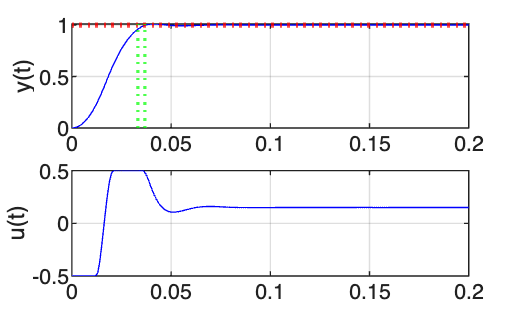

figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(1.01, ':r', 'LineWidth',1.2)
yline(0.99, ':r', 'LineWidth',1.2)
xline(0.035*1.05, ':g', 'LineWidth',1.2)
xline(0.035*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')

Now let's do it again changing Hp and Hu

Hp = 35;
Hu = 18;

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...



clear out

out = sim('sim_pendolum.slx');

Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.00
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.01
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.02
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.03
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.04
Update start, t=0.05
Update start,

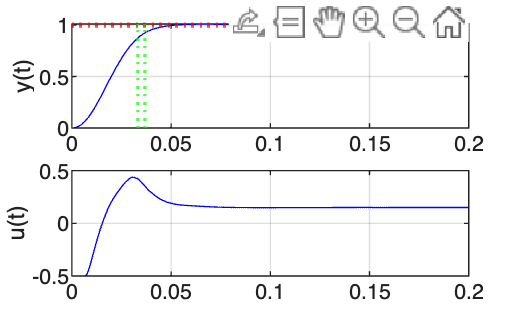

figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(1.01, ':r', 'LineWidth',1.2)
yline(0.99, ':r', 'LineWidth',1.2)
xline(0.035*1.05, ':g', 'LineWidth',1.2)
xline(0.035*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')